# Challenge One - Basic algorithms

Assume a *directed acyclic graph* (DAG) in which nodes can have multiple parents and there is a single unique root node. The minimum number of edges connecting any node $n$ with the DAG's root node $r$ is considered the depth $d\left(n\right)$ of node $n$ . Because a node can have many parents, there might be several routes, of varying number of edges, from the node to the root r . Provide a test (see *Test Driven Development*) that executes your solution and verifies, it works as expected. Then write the function that returns the depth of a node given the DAG and test it with your test. Assume the DAG, i.e. the input to your function, to be represented as an *adjacency matrix* . Another input argument is the root node, i.e. consider the root node to be known so that your algorithm does not need to find it. Use any programming language you like to solve this challenge. 

### A Graph

A graph $G$ is a finite nonempty set of objects, called vertices, together with a set of unordered pairs of distinct vertices, called edges. The set of vertices of a graph $G$ is called the vertex set of G, denoted by $V$, and the set of edges is called the edge set of $G$, denoted by $E$. The edge $e=\left\lbrace u,v\right\rbrace$ (or $e=\textrm{uv}$) is said to join the vertices $u$ and $v$. 

### Adjacency Matrix

The properties of a DAG's adjacency matrix $A\in {\mathbb{R}}^{\left\lbrack \textrm{nxn}\right\rbrack }$ is as follows:

- 
$$\textrm{tr}\left(A\right)=0$$


- 
$$A^n =0$$


- 
$$\det \left(A+I\right)=1$$


These properties are due the nature of the DAG, which creates a Nilpotent matrix. Here, the upper triangle of a sqaure matrix is considered.

### Bellman Ford Algorithm

Given a directed weighted graph $G=\left(V,E,w\right)$ and a source $n$ , the Bellman-Ford algorithm returns the shortest path length from s to every vertex. Bellman–Ford proceeds by relaxation, in which approximations to the correct distance are replaced by better  ones until they eventually reach the solution. The  approximate distance to each vertex is always an overestimate of the  true distance, and is replaced by the minimum of its old value and the  length of a newly found path.

#### Time Complexity

Worst Case: $\Theta \left(|V||E|\right)$; Best Case: $\Theta \left(|E|\right)$

## Intialize Graph

Please input the value $r$. In this instance, $r$ is the number of nodes and the index of the root node.

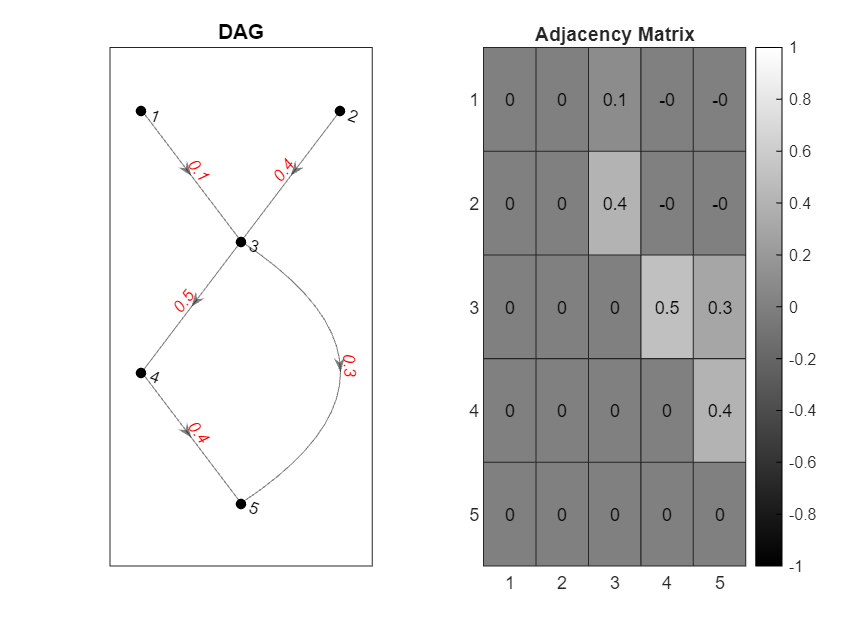

clf;
r=5; % Alle Wege fuehren nach Rom r
weightedEdges = true;
[A,G]=randomDAGAdjecencyMatrix(r, weightedEdges);
dagPlotter(G,A,weightedEdges);

### Bellman-Ford Algorithm

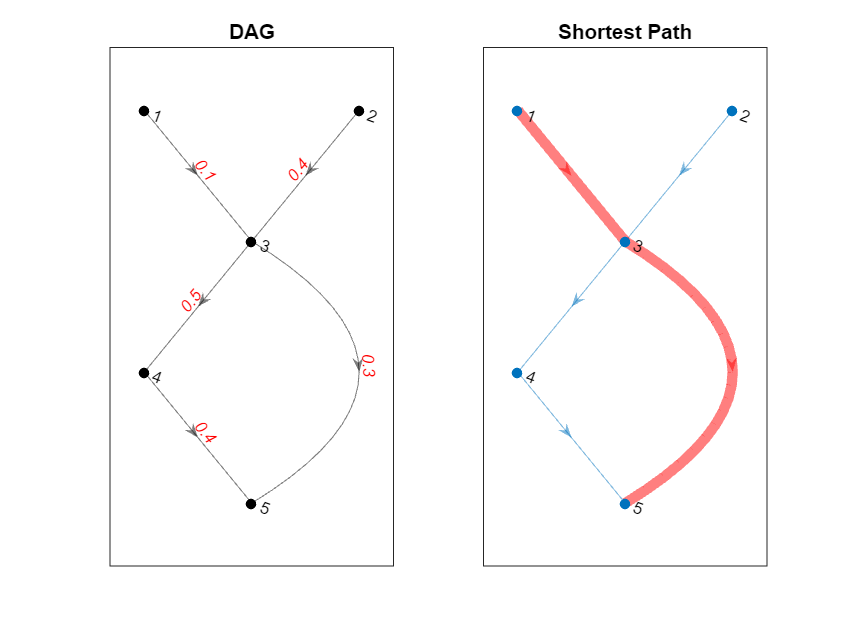

n = 1; % Choose your source
E = table2array(G.Edges);
[d,allIterations, totalCost, path] = bellmanFord(n,G,E,r);

#### **Minimum Cost Function d(n)**

The minimum number of edges connecting any node $n$ with the DAG's root node $r$ is considered the depth $d\left(n\right)$ of node $n$.

d

d = 1×5 table
    Node 1    Node 2    Node 3    Node 4    Node 5
    ______    ______    ______    ______    ______

      0        Inf       0.1       0.6       0.4  


#### Path of Minimum Cost

You can observe which nodes are traversed from source (n) to root (r)

path

path =      5     3     1


#### All Iterations of Bellman-Ford Algorithm

You can see how each iteration updates the cost of the shortest path.

allIterations

allIterations = 20×5 table
    Node 1    Node 2    Node 3    Node 4    Node 5
    ______    ______    ______    ______    ______

      0        Inf       Inf       Inf       Inf  
      0        Inf       0.1       Inf       Inf  
      0        Inf       0.1       Inf       Inf  
      0        Inf       0.1       0.6       Inf  
      0        Inf       0.1       0.6       0.4  
      0        Inf       0.1       0.6       0.4  
      0        Inf       0.1       0.6       0.4  
      0        Inf       0.1       0.6       0.4  
      0        Inf       0.1       0.6       0.4  
      0        Inf       0.1       0.6       0.4  
      0        Inf       0.1       0.6       0.4  
      0        Inf       0.1       0.6       0.4  
      0        Inf       0.1       0.6       0.4  
      0        Inf       0.1       0.

totalCost

totalCost = 0.4000

### BrainFuck

I coded a BrainFuck interpreter to resolve the DAG statement problem. Remove the % and press the button to run the interpreter. 

 
brainFuckInterpreter('script.txt') 

ans = 'I would rather go to dinner, please.'